
d = 6

d = 6


syms x y
syms a b
syms h
E(x,y,a,b,h) = h^2/((x-d*a)^2+(y-d*b)^2+h^2)^2

$$E(x, y, a, b, h) = \frac{h^{2}}{{\left({\left(6\,a-x\right)}^{2}+{\left(6\,b-y\right)}^{2}+h^{2}\right)}^{2}}$$


E_rec = symsum(symsum(E,a,-1,1),b,-1,1)

$$E\_rec(x, y, h) = \frac{h^{2}}{{\left({\left(x-6\right)}^{2}+{\left(y-6\right)}^{2}+h^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(x-6\right)}^{2}+{\left(y+6\right)}^{2}+h^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(x+6\right)}^{2}+{\left(y-6\right)}^{2}+h^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(x+6\right)}^{2}+{\left(y+6\right)}^{2}+h^{2}\right)}^{2}}+\frac{h^{2}}{{\left(h^{2}+x^{2}+y^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(x-6\right)}^{2}+h^{2}+y^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(x+6\right)}^{2}+h^{2}+y^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y-6\right)}^{2}+h^{2}+x^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y+6\right)}^{2}+h^{2}+x^{2}\right)}^{2}}$$

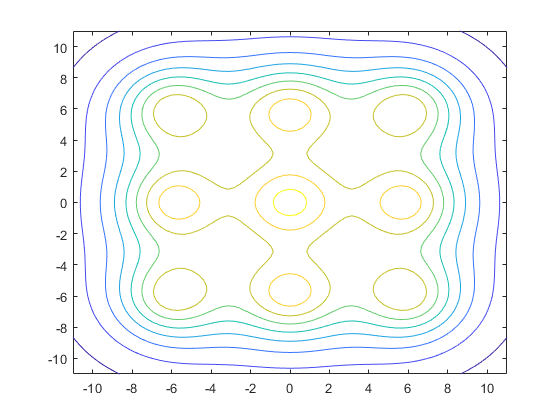


%ezsurf(E_rec(x,y,4),[-11,11])


fcontour(E_rec(x,y,4),[-11,11])

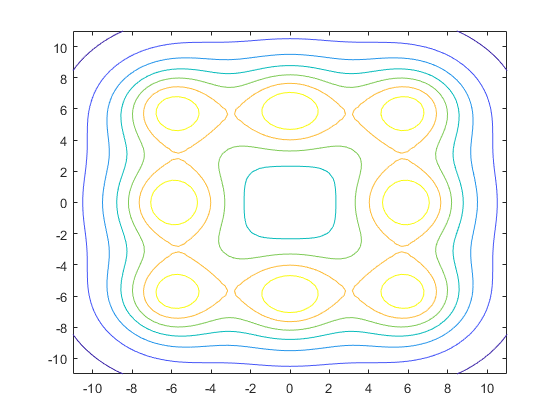

fcontour(E_rec(x,y,4)-E(x,y,0,0,4),[-11,11])

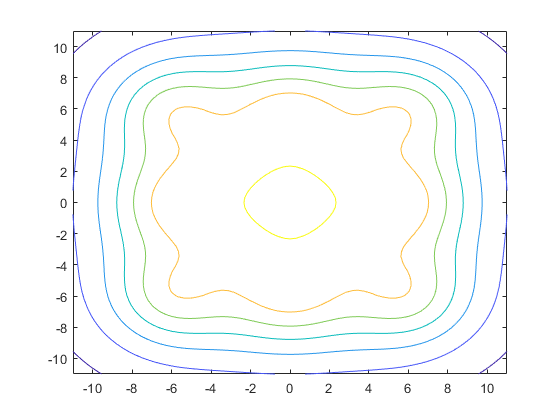

fcontour(E_rec(x,y,5),[-11,11])

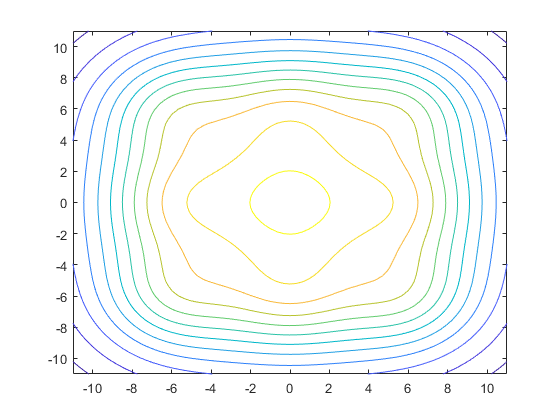

fcontour(E_rec(x,y,6),[-11,11])


syms k

E_hex(x,y,h) = E(x,y,0,0,h) + symsum(E(x,y,cos(k*pi/3+pi/6),sin(k*pi/3+pi/6),h),k,0,5)

$$E\_hex(x, y, h) = \begin{array}{l} \frac{h^{2}}{{\left(h^{2}+x^{2}+y^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y-6\right)}^{2}+h^{2}+x^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y+6\right)}^{2}+h^{2}+x^{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y-3\right)}^{2}+h^{2}+\sigma_{1}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y-3\right)}^{2}+h^{2}+\sigma_{2}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y+3\right)}^{2}+h^{2}+\sigma_{1}\right)}^{2}}+\frac{h^{2}}{{\left({\left(y+3\right)}^{2}+h^{2}+\sigma_{2}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\left(x-3\,\sqrt{3}\right)}^{2}\\ \sigma_{2}={\left(x+3\,\sqrt{3}\right)}^{2} \end{array}$$

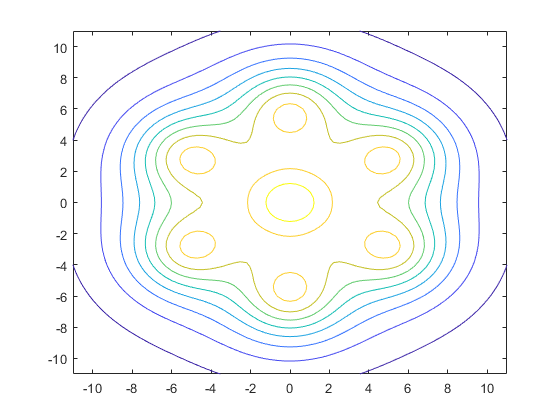


%ezsurf(E_hex(x,y,4),[-11,11])

fcontour(E_hex(x,y,4),[-11,11])

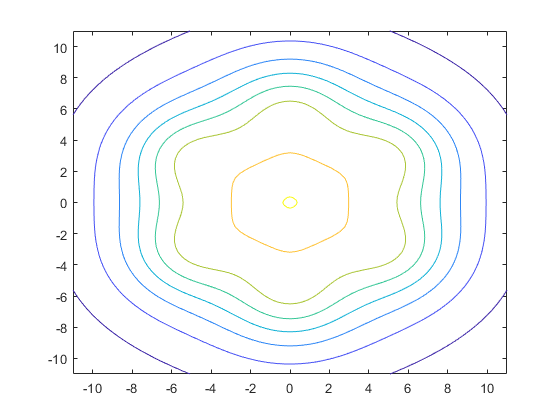

fcontour(E_hex(x,y,5),[-11,11])

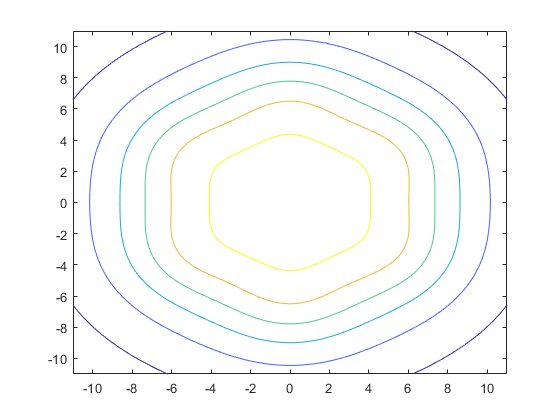

fcontour(E_hex(x,y,6),[-11,11])


E1 = E(0,0,0,0,5)

$$E1 = \frac{1}{25}$$

E_rmax = E_rec(0,0,5)

$$E\_rmax = \frac{67835889}{875272225}$$


Kr = double(E_rmax/(E_rmax-E1))

Kr = 2.0666


E_hmax = E_hex(0,0,4)

$$E\_hmax = \frac{265}{2704}$$

Kh = E_hmax/(E_hmax-E1)

$$Kh = \frac{6625}{3921}$$



clear;
clf;

d=6;
nrec=9;
h=5;

x=-4:0.1:16;
y=-4:0.1:16;
I_0 = 1;
[x,y] = meshgrid(x,y);



E_0=I_0*h.^2./(x.^2+y.^2+h.^2).^2;
E_rec = 0
for i=0:2
    for j=0:2
        E_rec = E_rec + I_0*h.^2./((x-i*d).^2+(y-j*d).^2+h.^2).^2;
    end
end

clf;

s = surf(x,y,E_rec-GenerateE(x,y,1*d,1*d,h,I_0));
s.EdgeColor = 'none';

view([0 90])
%colormap('hot')
axis equal
xlim([-4 16])

clf;


## 4 pixel hex vs rec

% Hex koordinaten
clear;
clf;
subplot(1,2,1);
x=-4:0.1:13;
y=-8.5:0.1:8.5;
[x,y] = meshgrid(x,y);
d = 6;
h=4;
I_0=1;
X = [0 1 1 2;0 0 -1 0]; % Koordinaten in hex system
%% i,j koordinaten in x,y transformieren
X_pos(2,length(X)) = 0;
for i=1:length(X)
    X_pos(:,i) = getHexPos(X(:,i),d);
end
X_pos;
E_hex_uniform = zeros(length(x)); %Matrix für E initialisiern
for i=1:length(X)
    X0 = getHexPos(X(:,i),d);
    E_hex_uniform = E_hex_uniform + GenerateE(x,y,X0(1),X0(2),h,I_0);
end

imagesc(x(1,:),y(:,1),E_hex_uniform); %scalierte farben
%s.EdgeColor = 'none'; %alt, von 3d surf
%uistack(s,'bottom');
%view([0 90]);

%% Sechsecke überlagern - weils geht
hold on;
axis equal;
for i=1:length(X)
    X0 = getHexPos(X(:,i),d);
    drawHex(X0,d);
end
ylim([-8 8]);


%% Rechteckige Verteilung berechnen

subplot(1,2,2);
x=-8.5:.1:8.5;
y=-8.5:0.1:8.5;
[x,y] = meshgrid(x,y);

X=[-1 -1 1 1; 1 -1 -1 1];
X_pos = X*d/2;
E_rec_uniform = zeros(length(x));
for i=1:length(X_pos)
    E_rec_uniform = E_rec_uniform + GenerateE(x,y,X_pos(1,i),X_pos(2,i),h,I_0);
end

s = imagesc(x(1,:),y(:,1),E_rec_uniform); %skalierte farben

for i=1:length(X_pos)
    drawRec(X_pos(:,i),6);
end

axis equal;
ylim([-8 8]);
